## 输入与输出

**各类数据类型**

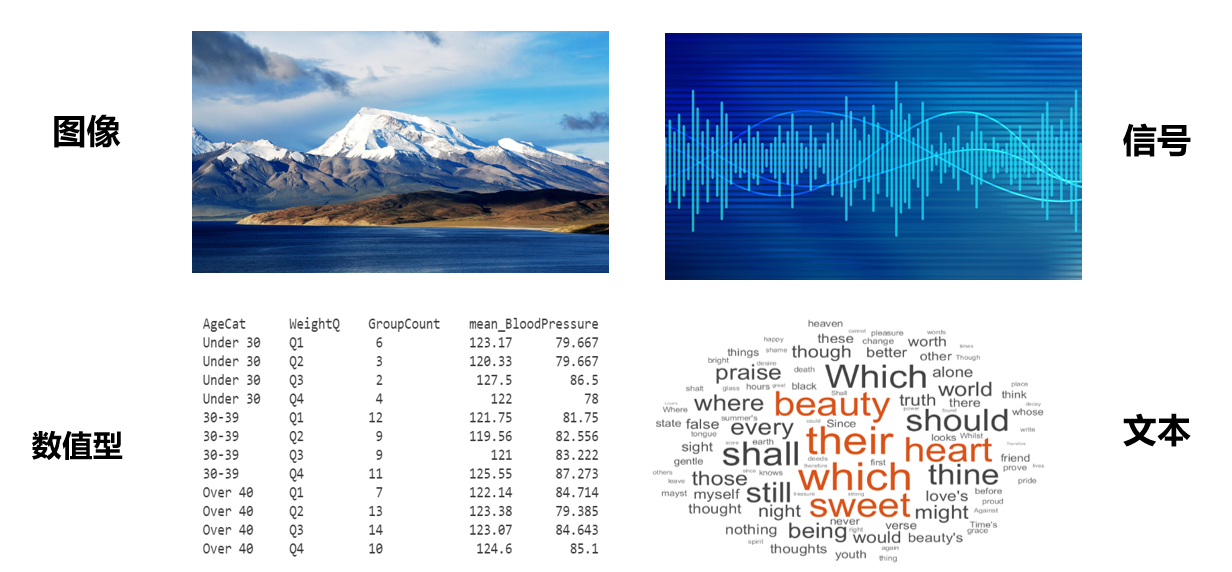

### 7.1 目标：读取电子表格

内容：某健康体检的血压数据保存在文件 bloodpressure.xls 中，请将该血压数据读入 MATLAB。

在 MATLAB 外打开该文件并查看数据。

% input the booldpressure data from a excel file
bpress = readtable("bloodpressure.xls")
% Open the file outside MATLAB for comparison
winopen bloodpressure.xls

### 7.2 目标：读取文本文件

内容：

同一体检的身高、体重数据保存在文本文件weightheight_q.txt 中，请读取该文件。

在 MATLAB 外打开并查看数据。

% Input the weight and height data from a text file
wheightQ = readtable("weightheight_q.txt")
% Open the file in the editor for comparison
edit weightheight_q.txt

### 7.3 目标：读取 CSV 文件

内容：

体检的部分数据保存在 bodymeasures.csv 文件中，请读取该文件。

% Read data from a csv file
body = readtable("bodymeasures.csv")

### 7.4 目标：读取 SAS XPORT 文件

内容：

体检的部分数据保存在 .xpt（XPORT）文件中，请读取该文件。

% Read
demog = xptread("demographics.xpt")

### 7.5 目标：将数据输出为 MAT 文件

内容：

把以上 4 个实验读入的数据整体保存到一个 .mat 文件；

重新读取该 .mat 文件，检查四项数据是否都能正确读入。

save("fourtables.mat","body","bpress","demog","wheightQ");
clear

load('fourtables.mat')


### 7.6 目标：读取图像并输出处理后的图像

内容：

1. 读取山峰图像 peak.jpg；

2. 将图像放大 2 倍；

3. 保存并输出放大后的图像。

I=imread('peak.jpg');
figure;
imshow(I);
J=imresize(I,2,'nearest');
figure;
imshow(J);
title('Enlarged image');
imwrite (J, 'LargerImg.jpg')

### 练习

提供的视频 visiontraffic.avi 为道路车辆监控画面，请完成以下任务：

1. 用红色框标记视频中的车辆；

2. 编写并运行程序，统计该视频中车辆的累计数量。

[https://www.mathworks.com/help/vision/ug/detecting-cars-using-gaussian-mixture-models.html](https://www.mathworks.com/help/vision/ug/detecting-cars-using-gaussian-mixture-models.html)

[https://www.mathworks.com/help/vision/ug/motion-based-multiple-object-tracking.html](https://www.mathworks.com/help/vision/ug/motion-based-multiple-object-tracking.html)